addpath(genpath('signals'))
addpath('signal_proc_functions')
load('unit_impulse_response.mat', 'unit_impulse_response')

sample_rate = 256; % sample rate for unit impulse response
pad = zeros(1, sample_rate * 20);

input = load('input_hc_seizure.mat');
output = load('output_hc_seizure.mat');

% downsample input to same rate as UIR
input_ds = resample(input.data, sample_rate, input.sample_rate);
input_ds = input_ds(2:end);

% zero output, pad with zeros, truncate for ease
output_signal = output.data - mean(output.data);
output_signal = [pad, output_signal(1:520*sample_rate), pad];

% deconvolve and clip reconstruction and output to be same length as input
recon = deconv(output_signal, unit_impulse_response);

recon = recon(1:length(input_ds));
output_signal = output_signal(1:length(input_ds));

% Input, output, and recon need to be temporally aligned for phase
% comparison.
% Make cross-correlogram and align signals using lag of maximum correlation
[input_recon_xcorr, lags] = xcorr(input_ds, recon, [], 'coeff');
[max_coeff, i_max_lag] = max(input_recon_xcorr)

max_coeff = 0.9932

i_max_lag = 116797

max_lag = lags(i_max_lag)

max_lag = -7256

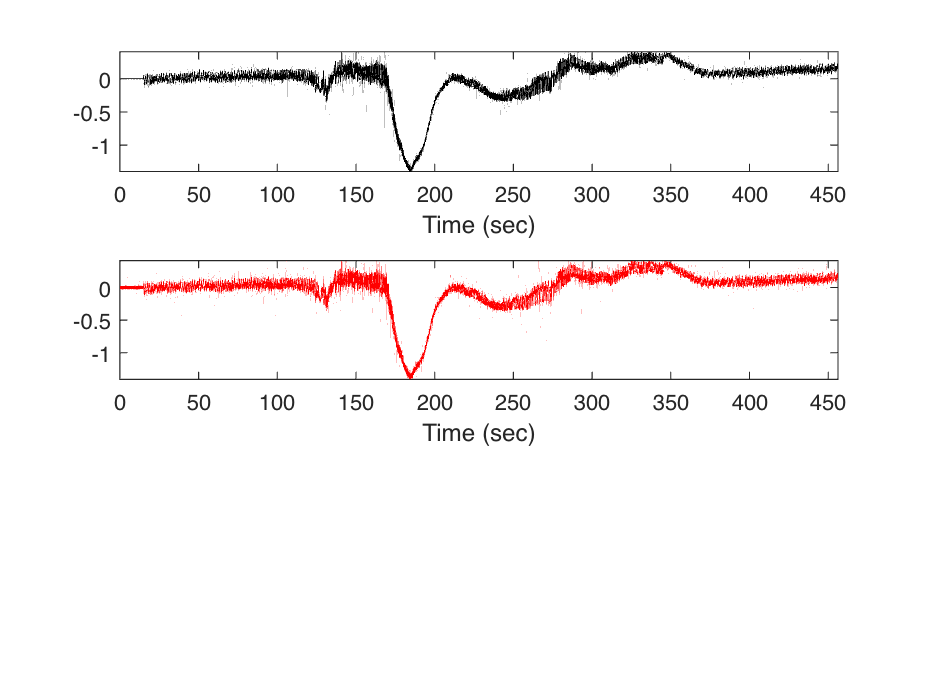


recon = recon(abs(max_lag) + 1:end);
output_signal = output_signal(abs(max_lag)+1:end);
input_ds = input_ds(1:length(recon));

% Plot to check alignment worked
figure
subplot(3,1,1)
plot_signal(input_ds, sample_rate, 'sec', 'k')

subplot(3,1,2)
plot_signal(recon, sample_rate, 'sec', 'r')

% normalize using z-score to make amplitudes comparable
input_ds = norm_z(input_ds);
output_signal = norm_z(output_signal);
recon = norm_z(recon);

% tolerance for inclusion in phase spectrum
tol = 1e-4;

% calculate amp spectra and phase spectra
[f_input, y1_input] = fft_transform(input_ds, sample_rate);

[f_output, y1_output] = fft_transform(output_signal, sample_rate);

[f_recon, y1_recon] = fft_transform(recon, sample_rate);

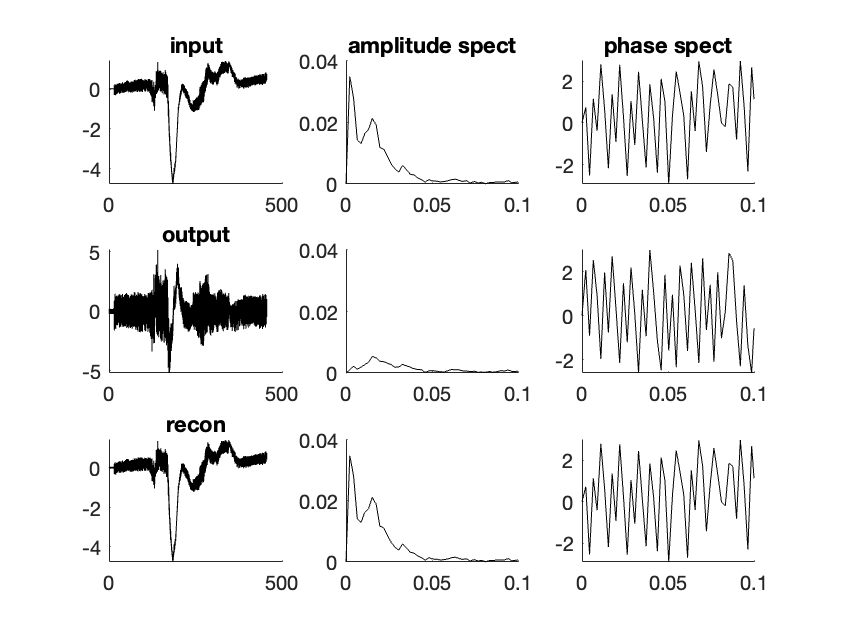


phase_input = y1_input;
amp_input = abs(y1_input);
amp_input = amp_input/sum(amp_input);
phase_input(amp_input < tol) = 0;
phase_input = angle(phase_input);

phase_output = y1_output;
amp_output = abs(y1_output);
amp_output = amp_output / sum(amp_output);
phase_output(amp_output < tol) = 0;
phase_output = angle(phase_output);

phase_recon = y1_recon;
amp_recon = abs(y1_recon);
amp_recon = amp_recon / sum(amp_recon);
phase_recon(amp_recon < tol) = 0;
phase_recon = angle(phase_recon);

t = (0:length(input_ds)-1)/sample_rate;

figure
ax1 = subplot(3,3,1); hold('on')
title('input')
plot(t, input_ds, 'k')

ax2 = subplot(3,3,2); hold('on')
title('amplitude spect')
plot(f_input, amp_input, 'k')
ylim([0, 0.04])

ax3 = subplot(3,3,3); hold('on')
title('phase spect')
plot(f_input, phase_input, 'k')


ax4 = subplot(3,3,4); hold('on')
title('output')
plot(t, output_signal, 'k')

ax5 = subplot(3,3,5); hold('on')
plot(f_output, amp_output, 'k')
ylim([0, 0.04])

ax6 = subplot(3,3,6); hold('on')
plot(f_output, phase_output, 'k')

ax7 = subplot(3,3,7); hold('on')
title('recon')
plot(t, recon, 'k')

ax8 = subplot(3,3,8); hold('on')
plot(f_recon, amp_recon, 'k')
ylim([0, 0.04])

ax9 = subplot(3,3,9); hold('on')
plot(f_recon, phase_recon, 'k')

linkaxes([ax2, ax3, ax5, ax6, ax8, ax9], 'x')
xlim([0,0.1])

% Correlation analyses
fprintf('\n correlation input vs. output')


 correlation input vs. output

[r, p] = corrcoef(input_ds, output_signal)

r =     1.0000    0.2191
    0.2191    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(input_ds))

n = 116797


fprintf('\n correlation input vs. recon')


 correlation input vs. recon

[r, p] = corrcoef(input_ds, recon)

r =     1.0000    0.9993
    0.9993    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(input_ds))

n = 116797


fprintf('\n correlation amplitude spectrum input vs. output')


 correlation amplitude spectrum input vs. output

[r, p] = corrcoef(amp_input, amp_output)

r =     1.0000    0.6631
    0.6631    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(amp_input))

n = 58399


fprintf('\n correlation amplitude spectrum input vs. recon')


 correlation amplitude spectrum input vs. recon

[r, p] = corrcoef(amp_input, amp_recon)

r =     1.0000    0.9995
    0.9995    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(amp_input))

n = 58399


fprintf('\n correlation phase spectrum input vs. output')


 correlation phase spectrum input vs. output

[r, p] = corrcoef(phase_input, phase_output)

r =     1.0000    0.7201
    0.7201    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(phase_input(amp_input > tol)))

n = 1280


fprintf('\n correlation phase spectrum input vs. recon')


 correlation phase spectrum input vs. recon

[r, p] = corrcoef(phase_input, phase_recon)

r =     1.0000    0.9002
    0.9002    1.0000


p =      1     0
     0     1


fprintf('n = %i', length(phase_input(amp_input > tol)))

n = 1280